pixelSize = 4.08e-6;
% pixelSize = 0.0010795; % convert pixel to meter, this may be wrong
f = 2.8e-3;
u0 = 644;
v0 = 364;

A = [ 1/pixelSize 0 644; 0 1/pixelSize 364; 0 0 1];
B = [f 0 0 0; 0 f 0 0; 0 0 1 0];
C = A*B

C =   686.2745         0  644.0000         0
         0  686.2745  364.0000         0
         0         0    1.0000         0



P = [-1 -1 2 1; 1 -1 2 1; 1 1 2 1; -1 1 2 1]';
% P = [0 0 2 1; 2 0 2 1; 2 2 2 1; 0 2 2 1]'

p1 = [-1 1 2 1]'

p1 =     -1
     1
     2
     1



p = C*P

p = 	1.0e+03 *

    0.6017    1.9743    1.9743    0.6017
    0.0417    0.0417    1.4143    1.4143
    0.0020    0.0020    0.0020    0.0020



X = [p(1,:) ./ p(3,:); 
     p(2,:) ./ p(3,:)]

X =   300.8627  987.1373  987.1373  300.8627
   20.8627   20.8627  707.1373  707.1373


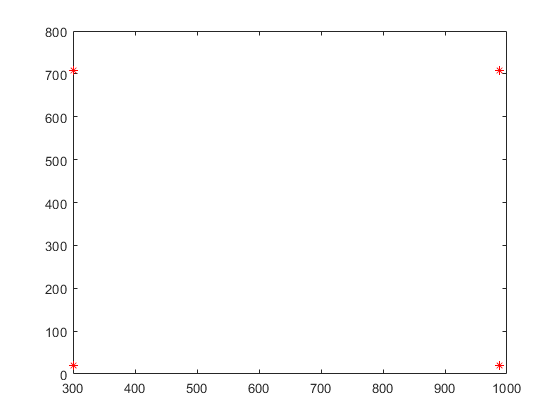


figure();
plot(X(1,:), X(2,:), 'r*');

% plot(X(1,1), X(2,1), 'r*');


## Test

C = [800 0 320 0; 0 800 240 0; 0 0 1 0];
P = [-0.3 0.1 3 1; 0.2 -0.2 3 1]';
p = C*P/3

p =   240.0000  373.3333
  266.6667  186.6667
    1.0000    1.0000
